# Code commenting

A colleague has recently left your development team at work. They were a great coder, but notoriously bad at commenting their work. Your boss has asked you to go through one of their scripts which contains some work on classifying hand-written letter shapes, and add comments that will help the rest of your team understand what's going on. You should add comments in your own words and you should prioritise clearly explaining what is going on to colleagues who may not have much experience of Machine Learning. It's fine if your comments go over more than one line.

The steps you should comment on, and the number of marks available for each comment are indicated below:

% add your comment here [1 mark]:
%remove all variables from the current Workspace
clear all;
%loading up dataset into a table
data = readtable('letterdata.csv');

% add your comment here [1 mark]: 
%re-seed Matlab's random number generator
rng(1);

% add your comment here [1 mark]: 
%shuffle the data
data_shuffled = data(randperm(size(data,1)), :);

% add your comment here [2 marks]: 
%create a testing dataset and a training dataset from the shuffled dataset
data_test = data_shuffled(1:1:16000, :);
data_train = data_shuffled(16001:1:end, :);

% add your comment here [2 marks]: 
%separate the labels and the examples for the testing data
test_labels = categorical(data_test{:,'letter'});
test_examples = data_test;
test_examples(:,'letter') = [];

% add your comment here [2 marks]: 
%separate the labels and the examples for the training data
train_labels = categorical(data_train{:,'letter'});
train_examples = data_train;
train_examples(:,'letter') = [];

% add your comment here [2 marks]: 
%train the descision tree classifier and save it in m - object containing
%the trained model
m = fitctree(train_examples, train_labels, 'MergeLeaves', 'off', 'Prune', 'off')

m =   ClassificationTree
           PredictorNames: {'xbox'  'ybox'  'width'  'height'  'onpix'  'xbar'  'ybar'  'x2bar'  'y2bar'  'xybar'  'x2ybar'  'xy2bar'  'xedge'  'xedgey'  'yedge'  'yedgex'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [A    B    C    D    E    F    G    H    I    J    K    L    M    N    O    P    Q    R    S    T    U    V    W    X    Y    Z]
           ScoreTransform: 'none'
          NumObservations: 4000


  Properties, Methods



% add your comment here [1 mark]: 
%generate prediction - classifying the data 
predictions = predict(m, test_examples);

% add your comment here [1 mark]: 
%outputing a confusion matrix
[c,order] = confusionmat(test_labels, predictions)

c =    544     5     0     1     1     1     2     7     0     0    11     6     6     0     3     0     1     3    20     1    16     0     0     5     2     0
     2   432     6    29     7    22    12    19    10     8    13     1     0     0     1     2     4    16    11     1     0     8     1     4     1     0
     0     3   435     0    12    10    23     2     2     0    11     5     1     0    11     0    10     5    10    14    11     0     1     1     0     1
     1    33     1   472     2     8     7    14     6     5     2     0     1    13    25    10     0     8    16     0     0     0     0     9     0     7
     8    16    21     1   455     5    18     0     2     4    10     7     0     0     0     0    11     5    17     1     0     2     1    12     1    23
     2    11     5     2     2   447     6     7     1     4     0     6     0     3     0    43     3     0    17    18     0    15     1     8     8     5
     3    19    18    14    21     2   431     3     0

order = 26×1 categorical array
     A 
     B 
     C 
     D 
     E 
     F 
     G 
     H 
     I 
     J 
     K 
     L 
     M 
     N 
     O 
     P 
     Q 
     R 
     S 
     T 
     U 
     V 
     W 
     X 
     Y 
     Z 



% add your comment here [2 marks]: 
%calculating the overall accuracy of the classifier
p = sum(diag(c)) / sum(c(:))

p = 0.7469

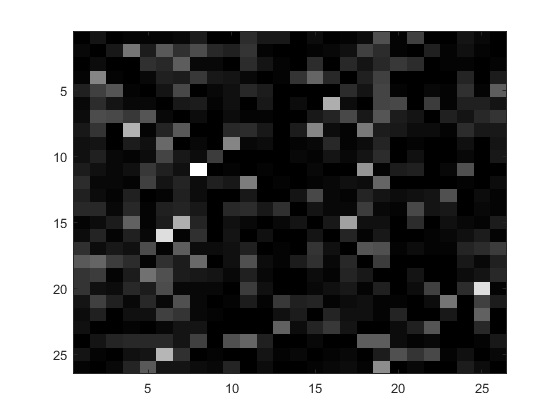


% add your comment here [2 marks]: 
%generating a color map with errors made by the classifier when classifying
%the testing examples
c_errors = c;
c_errors = c_errors - diag(diag(c_errors));
figure;
colormap('gray');
imagesc(c_errors)


% add your comment here [3 marks]: 
%determines the most common error when classifying the testig data
[~, m] = max(c_errors(:));
[i,j] = ind2sub(size(c_errors), m);
fprintf('%s mistaken for %s\n', order(i), order(j));

K mistaken for H


[Total: 20 marks]